# （HJQ & ZQ）编译码与误比特率计算

clear all, close all, clc
N = 30000;              % 数据量
x = randi(2, 1, N)-1;   % 传输数据
A_2 = [1 1 0 1          % 1/2效率
     1 1 1 1]';
A_3 = [1 0 1 1          % 1/3效率
     1 1 0 1
     1 1 1 1]';

% 不添加CRC
crc_code = x;

% 编码: conv / (8,3,4) / <combine>
code_conv2 = conv_encode(crc_code, A_2, 1);
code_conv3 = conv_encode(crc_code, A_3, 1);
code_834 = linear_encode(crc_code);
code_conv2_834 = linear_encode(code_conv2);
code_conv3_834 = linear_encode(code_conv3);
code_834_conv2 = conv_encode(code_834, A_2, 1);
code_834_conv3 = conv_encode(code_834, A_3, 1);

% 映射系数的调控
T=5;
mbit = 2;
snr=2;
% 映射参数按照snr与mbit进行配置
A=sqrt(snr/2);
Mmap1= [  -sqrt(2)  0;    sqrt(2)  0 ];
Mmap2 = [ -1 -1;    -1  1;    1 -1;    1  1 ];
Mmap3=[];
if mbit==1
    Mmap=A*Mmap1;
elseif mbit==2
    Mmap=A*Mmap2;
else
    Mmap=A*Mmap3;
end

% 映射
u_834 = mapping(code_834, 0, mbit,Mmap);
u_conv2 = mapping(code_conv2, 0, mbit,Mmap);
u_conv3 = mapping(code_conv3, 0, 1,Mmap1);
u_conv2_834 = mapping(code_conv2_834, 0, mbit);
u_conv3_834 = mapping(code_conv3_834, 0, mbit,Mmap);
u_834_conv2 = mapping(code_834_conv2, 0, mbit,Mmap);
u_834_conv3 = mapping(code_834_conv3, 0, 1,Mmap1);
% 信道传输
v_834 = channel(u_834, T, size(u_834, 2));
v_conv2 = channel(u_conv2, T, size(u_conv2, 2));
v_conv3 = channel(u_conv3, T, size(u_conv3, 2));
v_conv2_834 = channel(u_conv2_834, T, size(u_conv2_834, 2));
v_conv3_834 = channel(u_conv3_834, T, size(u_conv3_834, 2));
v_834_conv2 = channel(u_834_conv2, T, size(u_834_conv2, 2));
v_834_conv3 = channel(u_834_conv3, T, size(u_834_conv3, 2));
% 解映射
bit_834 = mapping(v_834, 1, mbit);
bit_conv2 = mapping(v_conv2, 1, mbit);
bit_conv3 = mapping(v_conv3, 1, mbit);
bit_conv2_834 = mapping(v_conv2_834, 1, mbit);
bit_conv3_834 = mapping(v_conv3_834, 1, mbit);
bit_834_conv2 = mapping(v_834_conv2, 1, mbit);
bit_834_conv3 = mapping(v_834_conv3, 1, 1);
% 硬判决译码
h_834 = linear_decode(bit_834);                     % (8,3,4)
h_conv2 = viterbi(bit_conv2, A_2, 1, "hard", Mmap); % conv2
h_conv3 = viterbi(bit_conv3, A_3, 1, "hard", Mmap); % conv3
temp = linear_decode(bit_conv2_834);
h_conv2 = viterbi(temp, A_2, 1, "hard", Mmap);      % conv2-(8,3,4)
temp = linear_decode(bit_conv3_834);
h_conv3 = viterbi(temp, A_3, 1, "hard", Mmap);      % conv3-(8,3,4)
temp = viterbi(bit_834_conv2, A_2, 1, "hard", Mmap);
h_834_conv2 = linear_decode(temp);                  % (8,3,4)-conv2
h_conv3 = viterbi(bit_834_conv3, A_3, 1, "hard", Mmap);
h_834_conv3 = linear_decode(temp);                  % (8,3,4)-conv3

## 统计误块率/误码率

% 解CRC
% [rh, eh, ~] = crc_judge(h)

函数或变量 'h' 无法识别。

% [rs, es, ~] = crc_judge(s)

% 统计误码率
wrg = find(rh-x);

% 可视化：错误图案
wid = 400;
len = N;
errimg = uint8(zeros(wid, len));
errimg(:, wrg) = 255;
imshow(errimg);

## 绘制误码率-SNR图像

以两种不同效率conv码1bit每符号的软硬判决为例

snr_dB=-20:4:20;
BER=repmat(snr_dB*0,[4,1]);
N = 30000;              % 数据量
x = randi(2, 1, N)-1;   % 保持传输数据不变
A_2 = [1 1 0 1          % 1/2效率
     1 1 1 1]';
A_3 = [1 0 1 1          % 1/3效率
     1 1 0 1
     1 1 1 1]';
% 绘图y轴数据准备
% 编码得到两份码流。映射前的过程与snr无关
code_conv2 = conv_encode(x, A_2, 1);
code_conv3 = conv_encode(x, A_3, 1);
for i=1:length(snr_dB)
    snr=10^(snr_dB(i)/10);
    T=5;
    mbit=1;
    % 映射的功率按照snr进行配置
    % 对于nbit/符号情况，请拷贝第二节中
    % "映射参数按照snr与mbit进行配置"的代码
    A=sqrt(snr/2);
    Mmap1= [  -sqrt(2)  0;    sqrt(2)  0 ];
    Mmap=A*Mmap1;
    % 两份码流过信道
    u_conv2 = mapping(code_conv2, 0, mbit,Mmap);
    u_conv3 = mapping(code_conv3, 0, mbit,Mmap);
    v_conv2 = channel(u_conv2, T, size(u_conv2, 2));
    v_conv3 = channel(u_conv3, T, size(u_conv3, 2));
    % part 1：硬判
        % 解映射
        bit_conv2 = mapping(v_conv2, 1, mbit);
        bit_conv3 = mapping(v_conv3, 1, mbit);
        % Viterbi硬判
        h_conv2 = viterbi(bit_conv2, A_2, 1, "hard", Mmap); % conv2
        h_conv3 = viterbi(bit_conv3, A_3, 1, "hard", Mmap);
    % part 2：软判
    s_conv2= viterbi(v_conv2, A_2, 1, "soft", Mmap);
    s_conv3= viterbi(v_conv3, A_3, 1, "soft", Mmap);
    % 各自统计误码率，并按h2、h3、s2、s3的顺序存入BER矩阵
    BER(1,i)=sum(abs(h_conv2-x))/N;
    BER(2,i)=sum(abs(h_conv3-x))/N;
    BER(3,i)=sum(abs(s_conv2-x))/N;
    BER(4,i)=sum(abs(s_conv3-x))/N;
end

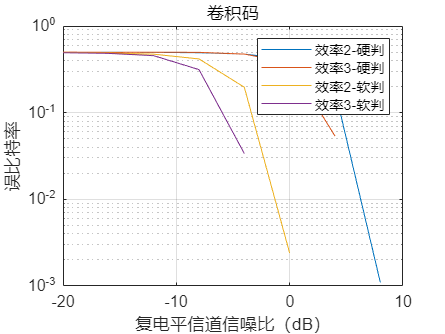

% 绘图
figure;
semilogy(snr_dB,BER(1,:),snr_dB,BER(2,:),snr_dB,BER(3,:),snr_dB,BER(4,:));
legend('效率2-硬判','效率3-硬判','效率2-软判','效率3-软判')
xlabel('复电平信道信噪比（dB）');
ylabel('误比特率');
title('卷积码')
grid